% 5 feb 2019

%EXERCISE 1

%A
syms q1 real
syms q2 real
syms q3 real
syms q4 real

syms a2 positive real
syms a3 positive real

syms d1 positive real
syms d4 positive real

alpha = [-pi/2, 0, -pi/2, 0];
a=[0,a2 , a3 ,0];
d=[d1,0,0,d4];
theta=[q1,q2,q3,q4];

table=[alpha',a',d',theta']

$$table = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & d_{1} & q_{1}\\ 0 & a_{2} & 0 & q_{2}\\ -\frac{\pi }{2} & a_{3} & 0 & q_{3}\\ 0 & 0 & d_{4} & q_{4} \end{array}\right)$$

%plot the robot
%Note: it has different format respect to Sveva's DHMatrix function
a_no_sym = double(subs(a, {a2,a3}, {0.1,0.1}));
alpha_no_sym = alpha;
d_no_sym = double(subs(d, {d1,d4}, {0.3,0.3}));
theta_no_sym = double(subs(theta, {q1,q2,q3,q4}, {0,0,0,0}));

DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym']

DHTable =          0   -1.5708    0.3000         0
    0.1000         0         0         0
    0.1000   -1.5708         0         0
         0         0    0.3000         0


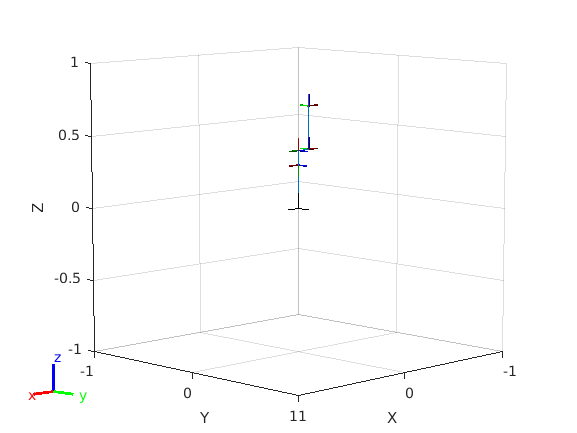

joints = 'RRRR';
robot_model = build_robot_model(joints, DHTable);

array_joint_values = [0,-pi/2, -pi/2, 0];
config = build_configuration(robot_model, array_joint_values);

show(robot_model, config);

i = 0

i = 0.7854

i = 1.5708

i = 2.3562

i = 3.1416

i = 3.9270

i = 4.7124

i = 5.4978

i = 6.2832

i = 7.0686

i = 7.8540

i = 8.6394

i = 9.4248

i = 10.2102

i = 10.9956

i = 11.7810

i = 12.5664

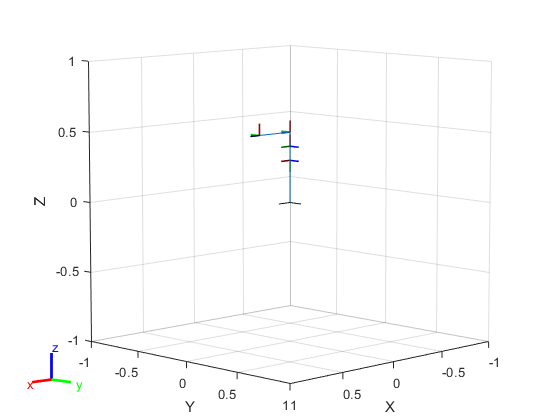

%animation
for i = 0 : pi/4 : 4*pi
    array_joint_values = [0,-pi/2,i,0];
    config = build_configuration(robot_model, array_joint_values);
    
    i
    show(robot_model, config);
    pause(0.25)
end

%B
[T, A] = DHMatrix(table);
A0_1=A{1}

$$A0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A1_2=A{2}

$$A1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & a_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & a_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2_3=A{3}

$$A2\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & -\sin\left(q_{3}\right) & a_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & 0 & \cos\left(q_{3}\right) & a_{3}\,\sin\left(q_{3}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3_4=A{4}

$$A3\_4 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & 0\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & 1 & d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T

$$T = \begin{array}{l} \left(\begin{array}{cccc} \sin\left(q_{1}\right)\,\sin\left(q_{4}\right)+\cos\left(q_{4}\right)\,\sigma_{2} & \cos\left(q_{4}\right)\,\sin\left(q_{1}\right)-\sin\left(q_{4}\right)\,\sigma_{2} & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{3}\\ -\cos\left(q_{1}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\sigma_{1} & \sin\left(q_{4}\right)\,\sigma_{1}-\cos\left(q_{1}\right)\,\cos\left(q_{4}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{3}\\ -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{4}\right) & \sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{4}\right) & -\cos\left(q_{2}+q_{3}\right) & d_{1}-d_{4}\,\cos\left(q_{2}+q_{3}\right)-a_{3}\,\sin\left(q_{2}+q_{3}\right)-a_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=a_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{4}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right) \end{array}$$


o4_h = [0 0 0 1]'

o4_h =      0
     0
     0
     1


p4_h = T*o4_h

$$p4\_h = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{4}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right)\\ \sin\left(q_{1}\right)\,\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{4}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right)\\ d_{1}-d_{4}\,\cos\left(q_{2}+q_{3}\right)-a_{3}\,\sin\left(q_{2}+q_{3}\right)-a_{2}\,\sin\left(q_{2}\right)\\ 1 \end{array}\right)$$

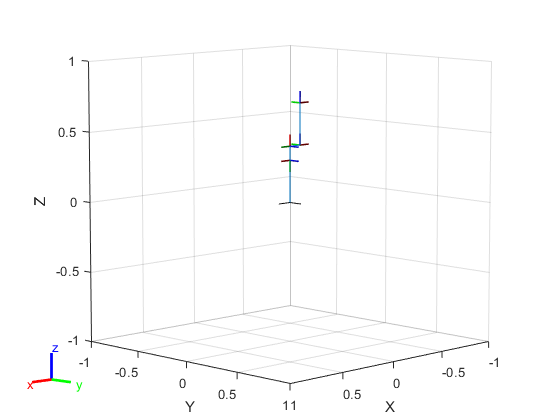

% D
q_s = [0,-pi/2, -pi/2, 0];
config = build_configuration(robot_model, q_s);

show(robot_model, config);


ps_h = subs(p4_h, {q1,q2,q3,q4}, {0,-pi/2, -pi/2, 0})

$$ps\_h = \left(\begin{array}{c} -a_{3}\\ 0\\ a_{2}+d_{1}+d_{4}\\ 1 \end{array}\right)$$

% E
q_0 = [0,0,0,0];

T_0 = subs(T, {q1,q2,q3,q4}, {0,0,0,0});
p4_4_tcp_h = [0 0.1 0.2 1]';
p0_4_tcp_h = T_0 * p4_4_tcp_h 

$$p0\_4\_tcp\_h = \left(\begin{array}{c} a_{2}+a_{3}\\ -\frac{1}{10}\\ d_{1}-d_{4}-\frac{1}{5}\\ 1 \end{array}\right)$$

% EXERCISE 2

% A
% Geometric Jacobian

f_r = get_f_r(T)

$$f\_r = \begin{array}{l} \left(\begin{array}{c} \cos\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{1}\right)\,\sigma_{1}\\ d_{1}-d_{4}\,\cos\left(q_{2}+q_{3}\right)-a_{3}\,\sin\left(q_{2}+q_{3}\right)-a_{2}\,\sin\left(q_{2}\right)\\ q_{1}+q_{2}+q_{3}+q_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{4}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right) \end{array}$$

[Jl, Ja] = geometric_jacobian(f_r, joints, [q1 q2 q3 q4], table);
f_r

$$f\_r = \begin{array}{l} \left(\begin{array}{c} \cos\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{1}\right)\,\sigma_{1}\\ d_{1}-d_{4}\,\cos\left(q_{2}+q_{3}\right)-a_{3}\,\sin\left(q_{2}+q_{3}\right)-a_{2}\,\sin\left(q_{2}\right)\\ q_{1}+q_{2}+q_{3}+q_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{4}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right) \end{array}$$

Jl

$$Jl = \begin{array}{l} \left(\begin{array}{cccc} -\sin\left(q_{1}\right)\,\sigma_{3} & -\cos\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & 0\\ \cos\left(q_{1}\right)\,\sigma_{3} & -\sin\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{1}\right)\,\sigma_{2} & 0\\ 0 & \sigma_{4}-\sigma_{5}-a_{2}\,\cos\left(q_{2}\right) & \sigma_{4}-\sigma_{5} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{4}\,\cos\left(q_{2}+q_{3}\right)+a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right)\\ \sigma_{2}=d_{4}\,\cos\left(q_{2}+q_{3}\right)+a_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{3}=\sigma_{5}-\sigma_{4}+a_{2}\,\cos\left(q_{2}\right)\\ \sigma_{4}=d_{4}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{5}=a_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

Ja

$$Ja = \left(\begin{array}{cccc} 0 & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 1 & 0 & 0 & -\cos\left(q_{2}+q_{3}\right) \end{array}\right)$$

% D
vb = [1 0 1]'

vb =      1
     0
     1



Jl_rank = rank(Jl)

Jl_rank = 3


% since rank is 3 = m then, each direction is feasible
% indeed the base of range space is eual to R^3
range_Jl_0 = orth(Jl_0)

$$range\_Jl\_0 = \begin{array}{l} \left(\begin{array}{ccc} 0 & -\frac{d_{4}}{\sqrt{{\left(a_{2}+a_{3}\right)}^{2}+{d_{4}}^{2}}} & -\frac{d_{4}\,\left({a_{2}}^{2}+a_{3}\,a_{2}\right)}{\sigma_{1}}\\ 1 & 0 & 0\\ 0 & -\frac{a_{2}+a_{3}}{\sqrt{{\left(a_{2}+a_{3}\right)}^{2}+{d_{4}}^{2}}} & \frac{a_{2}\,{d_{4}}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{{a_{2}}^{2}\,{d_{4}}^{4}}{{\left({a_{2}}^{2}+2\,a_{2}\,a_{3}+{a_{3}}^{2}+{d_{4}}^{2}\right)}^{2}}+\frac{{d_{4}}^{2}\,{\left({a_{2}}^{2}+a_{3}\,a_{2}\right)}^{2}}{{\left({a_{2}}^{2}+2\,a_{2}\,a_{3}+{a_{3}}^{2}+{d_{4}}^{2}\right)}^{2}}}\,\left({a_{2}}^{2}+2\,a_{2}\,a_{3}+{a_{3}}^{2}+{d_{4}}^{2}\right) \end{array}$$

rref(range_Jl_0)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$


qv_b = linsolve(Jl, vb)

$$qv\_b = \begin{array}{l} \left(\begin{array}{c} -\frac{\sin\left(q_{1}\right)}{\sigma_{8}\,\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{4}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right)}\\ -\frac{\sigma_{5}-\sigma_{6}+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}}{\sigma_{7}}\\ \frac{\sigma_{5}-\sigma_{6}-a_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}+a_{2}\,{\cos\left(q_{1}\right)}^{2}\,\sin\left(q_{2}\right)+a_{2}\,{\sin\left(q_{1}\right)}^{2}\,\sin\left(q_{2}\right)}{\sigma_{7}}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\sin\left(q_{2}+q_{3}\right)\,{\sin\left(q_{1}\right)}^{2}\\ \sigma_{2}=d_{4}\,\cos\left(q_{2}+q_{3}\right)\,{\sin\left(q_{1}\right)}^{2}\\ \sigma_{3}=a_{3}\,\sin\left(q_{2}+q_{3}\right)\,{\cos\left(q_{1}\right)}^{2}\\ \sigma_{4}=d_{4}\,\cos\left(q_{2}+q_{3}\right)\,{\cos\left(q_{1}\right)}^{2}\\ \sigma_{5}=d_{4}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \sigma_{6}=a_{3}\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \sigma_{7}=\sigma_{8}\,\left(a_{2}\,d_{4}\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{2}\right)-a_{2}\,a_{3}\,\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{2}\right)+a_{2}\,a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{2}\right)+a_{2}\,d_{4}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{2}\right)\right)\\ \sigma_{8}={\cos\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2} \end{array}$$

rref(qv_b)

$$ans = \left(\begin{array}{c} 1\\ 0\\ 0\\ 0 \end{array}\right)$$


Jl_0(:,1:3)^-1 * vb

$$ans = \left(\begin{array}{c} 0\\ \frac{a_{3}}{a_{2}\,d_{4}}-\frac{1}{a_{2}}\\ \frac{1}{a_{2}}-\frac{a_{2}+a_{3}}{a_{2}\,d_{4}} \end{array}\right)$$